# Problema 2

%PB1
function coeffs = spline_natural(x, y)
% INPUT:
%   x - vectorul nodurilor (valori strict crescatoare) [x0, x1, ..., xn]
%   y - vectorul valorilor functiei f(x) in aceste noduri [y0, y1, ..., yn]
%
% OUTPUT:
%   coeffs - structura care contine coeficientii pentru fiecare polinom cubic
%            pe intervalul [x(i), x(i+1)]:
%       coeffs.a - coeficientul liber (corespunde y(i))
%       coeffs.b - coeficientul lui (x - x_i)
%       coeffs.c - coeficientul lui (x - x_i)^2
%       coeffs.d - coeficientul lui (x - x_i)^3
%       coeffs.x - capetele stangi ale intervalelor (x(1:end-1))

    n = length(x);            % numarul de noduri
    h = diff(x);              % pasii h(i) = x(i+1) - x(i)

    alpha = zeros(n-1,1);     % partea dreaptă a sistemului tridiagonal

    % Construim vectorul alpha pentru interior (i = 2,..,n-1)
    for i = 2:n-1
        alpha(i) = (3/h(i))*(y(i+1) - y(i)) - (3/h(i-1))*(y(i) - y(i-1));
    end

    % Initializam vectorii pentru metoda Thomas (rezolvarea sistemului tridiagonal)
    l = ones(n,1);    % diagonala principala (initializata cu 1)
    mu = zeros(n,1);  % coeficientii de pe supradiagonala
    z = zeros(n,1);   % solutia temporara pentru sistemul tridiagonal

    % Construim sistemul tridiagonal pentru determinarea coeficientilor c
    for i = 2:n-1
        l(i) = 2*(x(i+1) - x(i-1)) - h(i-1)*mu(i-1);  % diagonala principala actualizata
        mu(i) = h(i)/l(i);                           % supradiagonala
        z(i) = (alpha(i) - h(i-1)*z(i-1))/l(i);       % partea dreapta
    end

    % Vectorii coeficientilor spline-ului
    a = y;                     % coeficientul liber este y(i)
    b = zeros(n-1,1);          % coeficientul lui (x - x_i)
    c = zeros(n,1);            % coeficientul lui (x - x_i)^2
    d = zeros(n-1,1);          % coeficientul lui (x - x_i)^3

    % Back-substitution pentru determinarea lui c (derivata a doua)
    for j = n-1:-1:1
        c(j) = z(j) - mu(j)*c(j+1);   % c(i) calculat din dreapta spre stanga
        b(j) = (a(j+1) - a(j))/h(j) - h(j)*(2*c(j) + c(j+1))/3;  % coef. liniar
        d(j) = (c(j+1) - c(j)) / (3*h(j));                       % coef. cubic
    end

    % Grupam coeficientii in structura de iesire
    coeffs = struct('a', a(1:end-1), ...  % toate a(i) pentru i=1,..,n-1
                    'b', b, ...
                    'c', c(1:end-1), ...
                    'd', d, ...
                    'x', x(1:end-1));    % capetele intervalelor

end

function values = eval_spline_N(x_eval, coeffs)
% INPUT:
%   x_eval - vectorul cu puncte unde dorim sa evaluam spline-ul
%   coeffs - structura cu coeficientii spline-ului, obtinuta din spline_natural():
%       .a - coeficientul liber
%       .b - coeficientul lui (x - x_i)
%       .c - coeficientul lui (x - x_i)^2
%       .d - coeficientul lui (x - x_i)^3
%       .x - vectorul cu capetele stangi ale intervalelor [x_0, x_1, ..., x_{n-1}]
%
% OUTPUT:
%   values - vector cu valorile spline-ului evaluate in fiecare punct din x_eval

    n = length(coeffs.x);               % numarul de intervale (n = nr. noduri - 1)
    values = zeros(size(x_eval));      % initializam vectorul rezultat

    % Parcurgem fiecare punct unde vrem sa evaluam spline-ul
    for i = 1:length(x_eval)
        % Cautam in ce interval [x_j, x_{j+1}] se afla x_eval(i)
        for j = 1:n
            % Verificam daca punctul se afla in intervalul curent
            if x_eval(i) >= coeffs.x(j) && (j == n || x_eval(i) < coeffs.x(j+1))
                dx = x_eval(i) - coeffs.x(j);  % distanta fata de capatul stang al intervalului

                % Aplicam formula polinomului spline pe intervalul [x_j, x_{j+1}]:
                % S(x) = a_j + b_j*(x - x_j) + c_j*(x - x_j)^2 + d_j*(x - x_j)^3
                values(i) = coeffs.a(j) + ...
                            coeffs.b(j)*dx + ...
                            coeffs.c(j)*dx^2 + ...
                            coeffs.d(j)*dx^3;

                break;  % am gasit intervalul potrivit, iesim din bucla interioara
            end
        end
    end
end

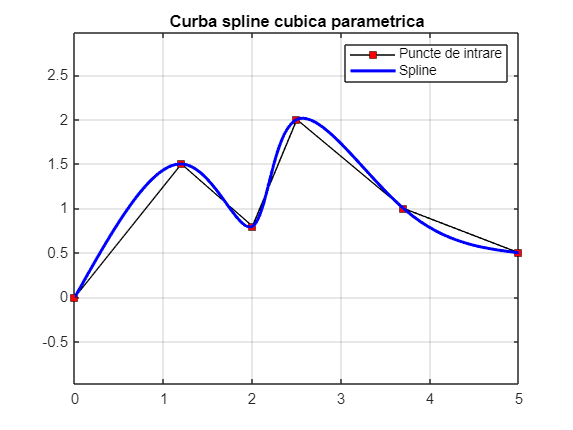

% Coordonate puncte
px = [0 1.2 2 2.5 3.7 5];
py = [0 1.5 0.8 2.0 1.0 0.5];

% Parametru artificial uniform
t = 1:length(px);

% Construim spline-urile pentru fiecare coordonată
coef_px = spline_natural(t, px);
coef_py = spline_natural(t, py);

% Evaluam spline-ul in puncte dese
t_eval = linspace(t(1), t(end), 300);
x_eval = eval_spline_N(t_eval, coef_px);
y_eval = eval_spline_N(t_eval, coef_py);

% Afisare grafica
figure;
plot(px, py, 'ks-', 'MarkerFaceColor', 'r'); hold on;
plot(x_eval, y_eval, 'b-', 'LineWidth', 2);
title('Curba spline cubica parametrica');
legend('Puncte de intrare', 'Spline');
axis equal;
grid on;